time5 = DYOErun2potential1657170.AnalogChannels; 
signal5 = DYOErun2potential1657170.VarName5; 
k = [time5,signal5]; 

% determine sampling frequency
Fs = 1 / mean(diff(time5));  % Sampling frequency in Hz



% analyze frequency components
Y = fft(signal5);
L = length(signal5);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

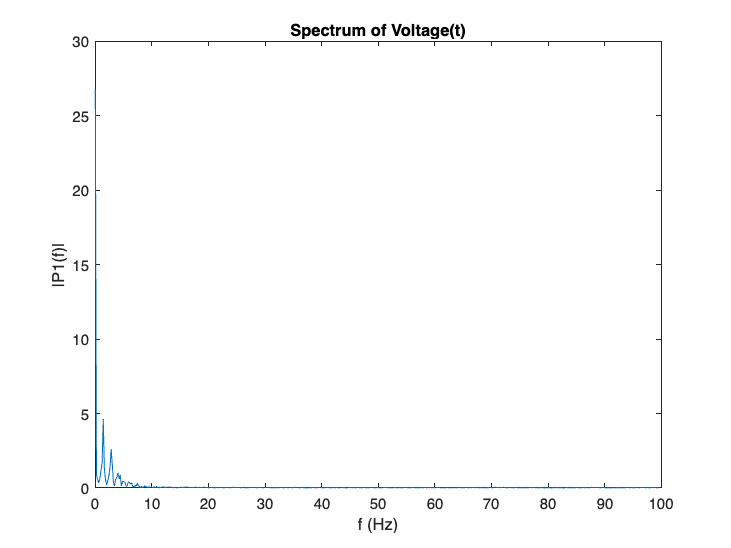

P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f, P1);
title('Spectrum of Voltage(t)');
xlabel('f (Hz)');
ylabel('|P1(f)|');

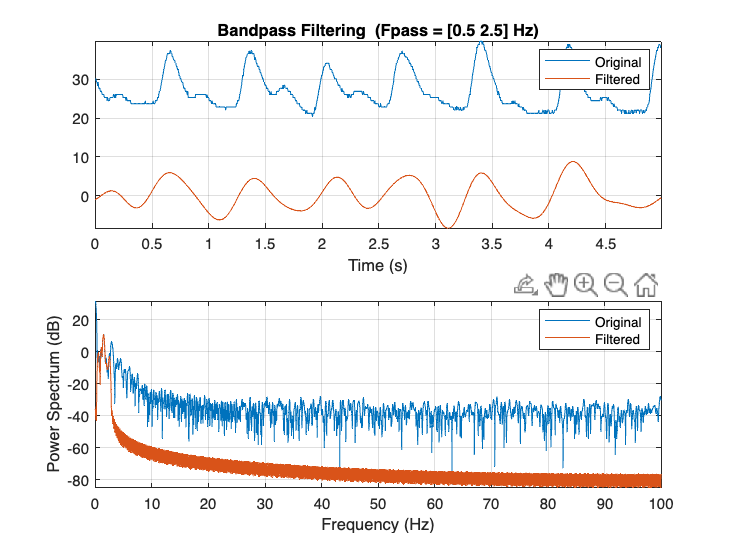

bandpass(signal5,[0.5 2.5],Fs)